# Stability

We have seen in Chapter 6 that some steady state solutions of differential equations are stable, and some are unstable. We can use the computer to invstigate what this means. Let's consider the system of first order equations


$$\frac{dx}{dt} = xy+2y, \qquad \frac{dy}{dt} = xy - 2x$$


First, we can plot out the phase plane for the system.

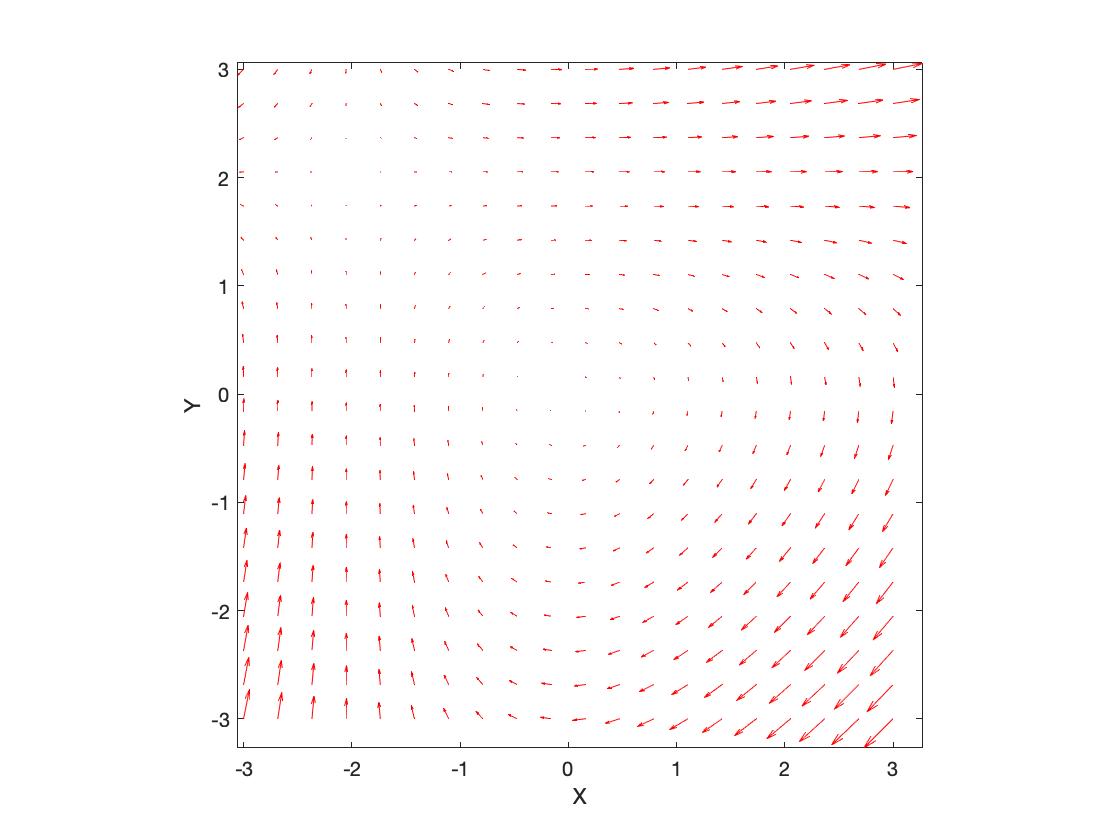

fcn = @(t,x) [x(1)*x(2) + 2.0*x(2); x(1)*x(2) - 2.0*x(1)];

x_min = -3;
x_max = 3;
y_min = -3;
y_max = 3;
n_x = 20;
n_y = 20;

% Calculate and plot the phase plane. 
t = PhasePlaneMMEES(fcn, x_min, x_max, n_x, y_min, y_max, n_y);

This system has two steady states, one at the origin and at (-2,2). 

***Exercise:**** Show that the origin is a stable steady state (a center) and the other point is an unstable saddle point. *

Let's look at the nature of some trajectories that start with different initial conditions. As a first point, let's consider starting somehwere neatr the origin.

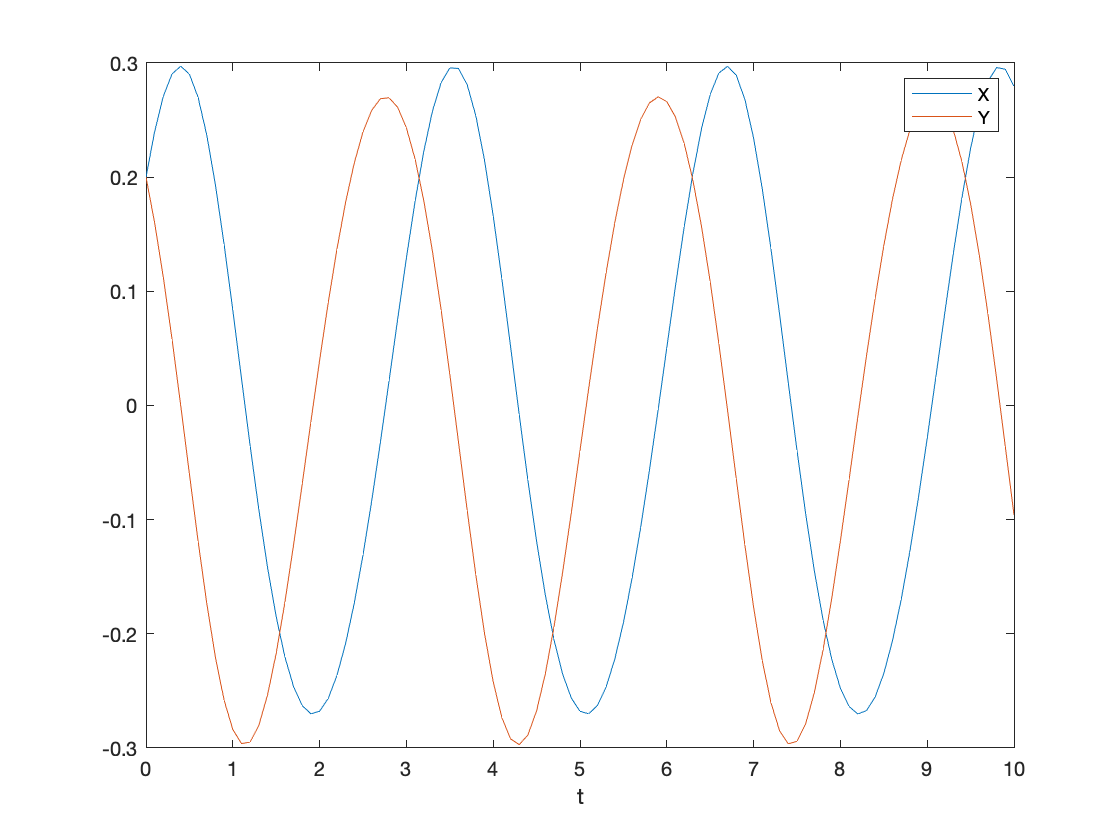

t_initial = 0.0;
t_final   = 10.0;
delta_t   = 0.1;

x_initial = 0.2;
y_initial = 0.2;

[t,y] = ode45(fcn, [t_initial:delta_t:t_final], [x_initial; y_initial]);
figure
plot(t,y)
xlabel('t')
legend('X', 'Y')

As expected, we see that the solutions exhibit oscillations around the origin. The two variables oscillate out of phase with each other.

***Exercise:**** Plot some more trajectories starting at points (0.2,0.1) and (0.1,0.2). Comment on what you notice aout teh behavior of the trajectories. *

Now let's start the trajectories a bit further from the origin.

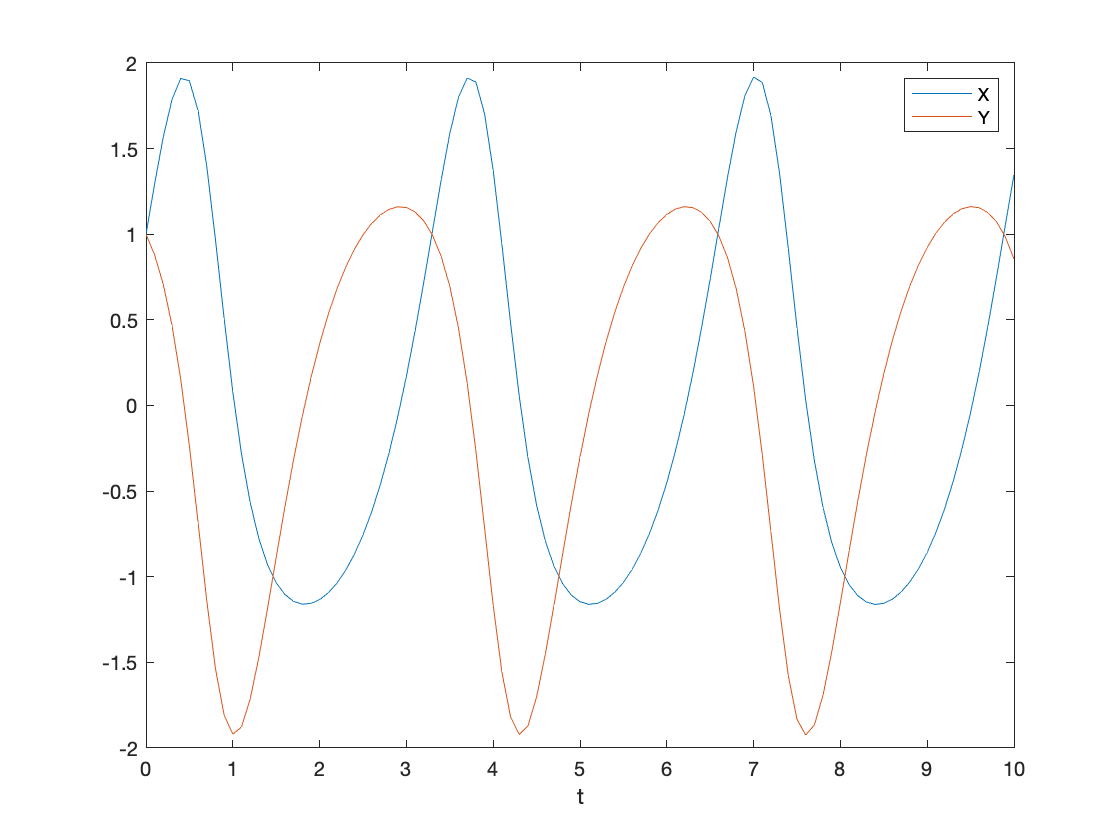

x_initial = 1.0;
y_initial = 1.0;

[t,y] = ode45(fcn, [t_initial:delta_t:t_final], [x_initial; y_initial]);
figure
plot(t,y)
xlabel('t')
legend('X', 'Y')

Again, the two variables show an oscillating behavior, but the oscillations are not as symmetric as the first case we looked at — the curves show both sharp peaks and rounded peaks. However, the trajectories are still osciallting around the origin. Let's move further away from the origin.

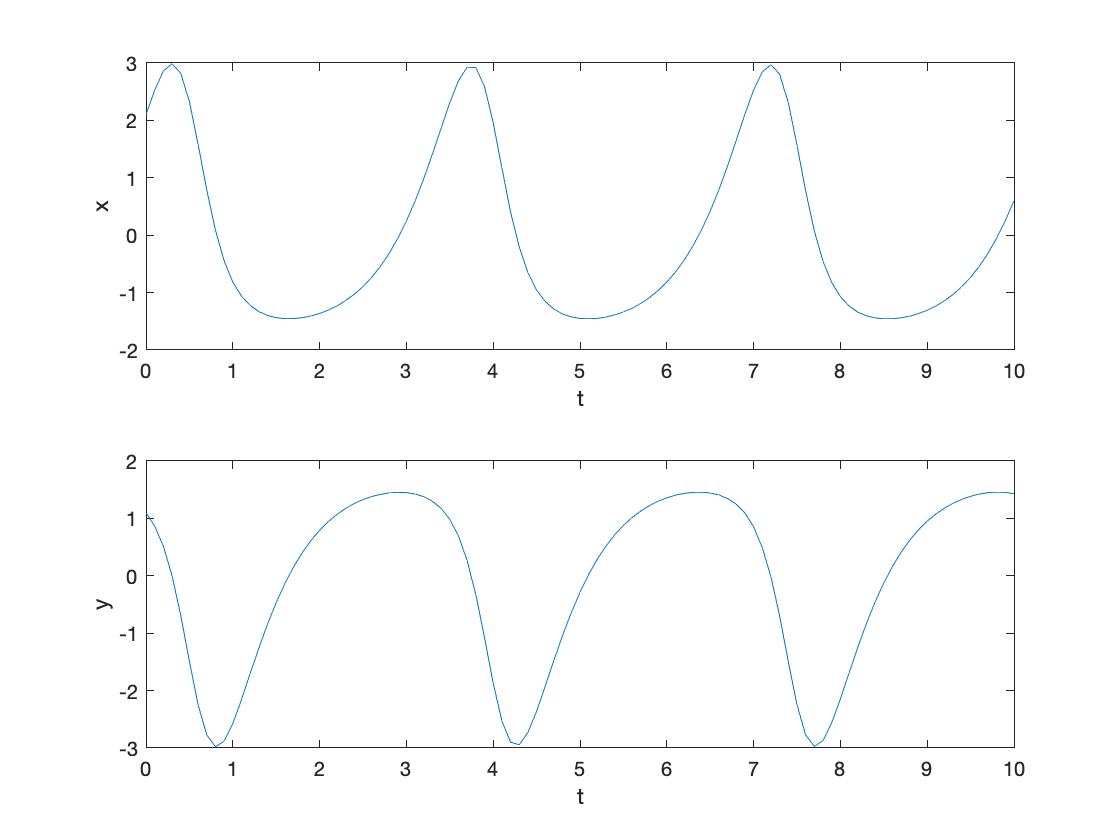

x_initial = 2.1;
y_initial = 1.1;

[t,y] = ode45(fcn, [t_initial:delta_t:t_final], [x_initial; y_initial]);
figure
subplot(2,1,1)
plot(t,y(:,1))
xlabel('t')
ylabel('x')
subplot(2,1,2)
plot(t,y(:,2))
xlabel('t')
ylabel('y')

The asymmetry in the oscillations is now even more pronounced. 

***Exercise:**** Describe what the asymmetriy in the trajectory means for the motion of the corresponding point in the phase plane — howfast will a point on the trajectory move in the phase plane? *

Let's move once more and look at a trajectory starting from another point.

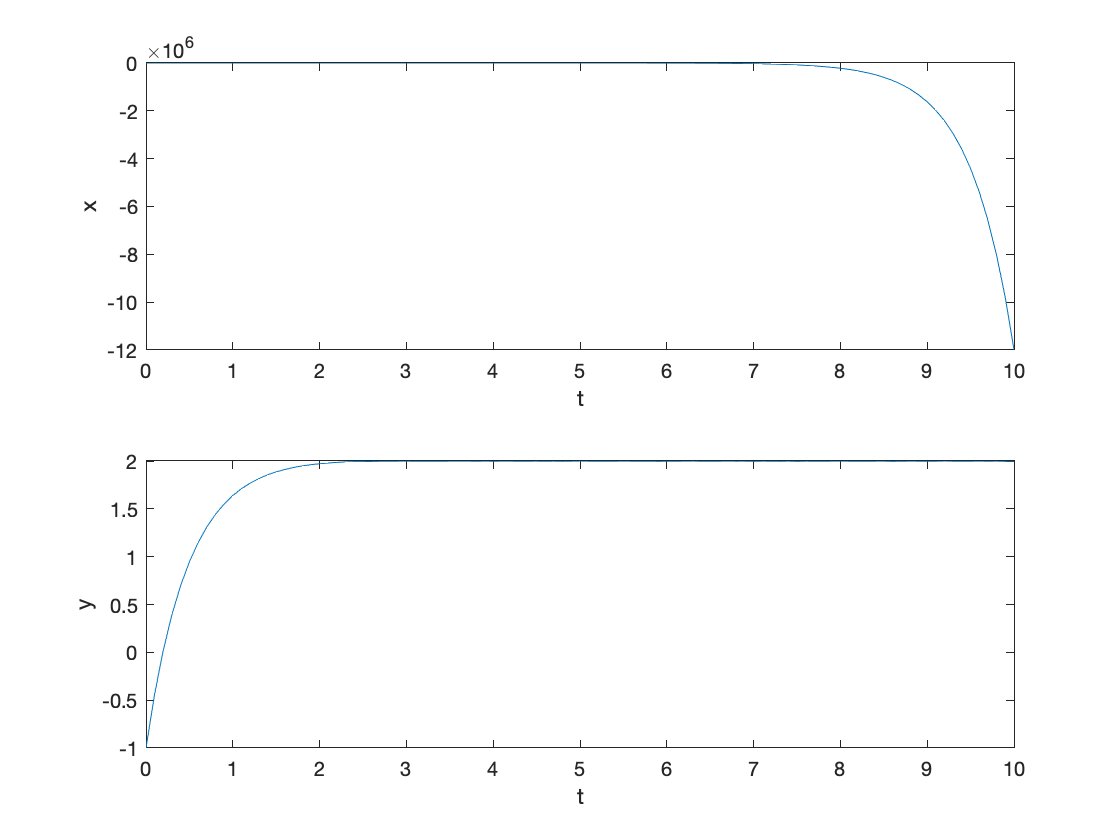

x_initial = -2.1;
y_initial = -1.0;

[t,y] = ode45(fcn, [t_initial:delta_t:t_final], [x_initial; y_initial]);
figure
subplot(2,1,1)
plot(t,y(:,1))
xlabel('t')
ylabel('x')
subplot(2,1,2)
plot(t,y(:,2))
xlabel('t')
ylabel('y')

Here we see a completely different type of behavior: one variable seems to be charging off to very large negative values while the other is tending to a constant. This is the typical behavior of a saddle point. 

***Exercise:**** Plot some more trajectories starting at different points. *

***Exercise: ****Plot the phase plane of the equations *


$$\frac{dx}{dt} = 8 - x^2 - y^2,\qquad  \frac{dy}{dt} = x^2 - y^2$$


*Calculate the steady states and plot some representative trajectories showing the different behaviors the trajectories can have. *

This exercise shows it is best to use a combined analytical and numerical approach to investigating the behaviors of solutions of differential equations. If we have just relied on numerical methods we may have missed some important behavior because we hadn't picked the right initial conditions. Similarly, being able to visualize the behavior of the solutions from hte numerical calculations is very valuable in understanding how different types of solutions evolve. 